# ELECTROMYOGRAPHY (EMG) OF THE EXTRAOCULAR MUSCLES (EOM)

- Main Code: [https://github.com/vasanza/EOG](https://github.com/vasanza/EOG)

- `IEEEDataPort: `[https://dx.doi.org/10.21227/bhpj-mz94](https://dx.doi.org/10.21227/bhpj-mz94)

- `More Matlab Examples: `[https://github.com/Human-Machine-Interface](https://github.com/Human-Machine-Interface)

- Hardware: Instrumentation amplifier based on AD620

- Sampling Frequency = 120 Hz for approximately 2 seconds

- Electrical activity of EOG signals: Fmin=8 and Fmax=31

- Subjects: 10

# Raw dataset preparation

clear;clc;%clear all
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
folders = FindFolders(datapath);
allData=[];

# Raw dataset preprocessing

#### % In this example no filtering was done, but it can be done

for i=1:length(folders)% Through all folders
    folderpath=fullfile(datapath,folders(i).name);%Select i folder
    filenames = FindCSV(folderpath);%List All CSV files
    for j=1:length(filenames)% Through all files
        data=readtable(fullfile(folderpath,filenames(j).name));%Select i CSV file
        dataNew=table2array(data);% Array Double
        dataNew(isnan(dataNew)) = 0;%Remove NAN numbers
        DataNorm = fNormalization(dataNew);%Normalization
        Label = fLabelEOG(folders(i).name);%Name Folder to Label
        
        %max(EOG1,EOG2), min(EOG1,EOG2), mean(EOG1,EOG2), median(EOG1,EOG2),...
        %rms(EOG1,EOG2), std(EOG1,EOG2)
        DataFeatures = [max(DataNorm) min(DataNorm) mean(DataNorm)...
            median(DataNorm) rms(DataNorm) std(DataNorm) Label];%Feature extraction
        allData=[allData;DataFeatures];
    end
end

# Plot Raw EOG dataset

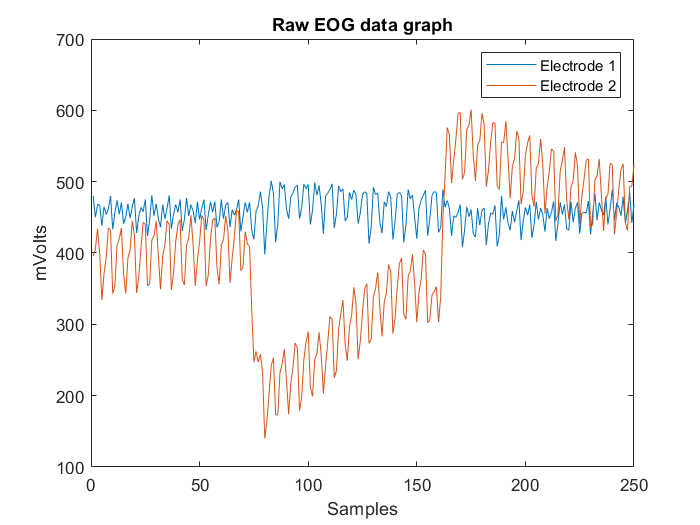

figure
plot(dataNew);xlabel('Samples');ylabel('mVolts');
title('Raw EOG data graph');
legend('Electrode 1','Electrode 2');

# Plot Normalization EOG dataset

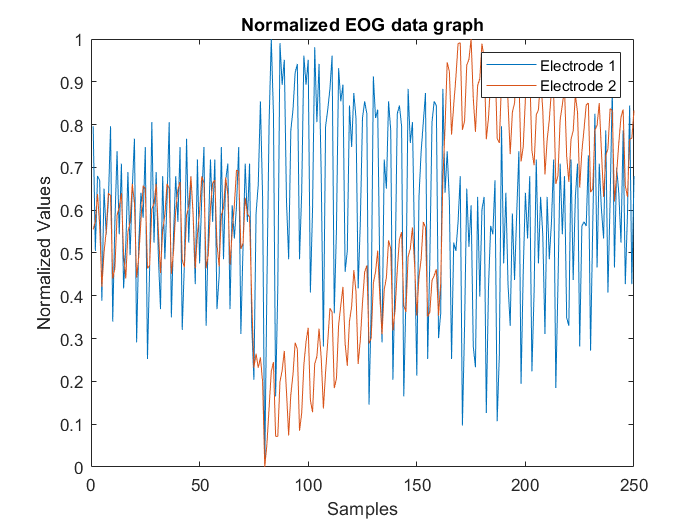

figure
plot(DataNorm);xlabel('Samples');ylabel('Normalized Values');
title('Normalized EOG data graph');
legend('Electrode 1','Electrode 2');

# Feature Selection

%max(EOG1,EOG2), min(EOG1,EOG2), mean(EOG1,EOG2), median(EOG1,EOG2),...
        %rms(EOG1,EOG2), std(EOG1,EOG2)
DataFeatureSelection=allData(1:end-1,1:end-1);%not including the label
R = corrcoef(DataFeatureSelection)

R =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN    1.0000   -0.2582    0.9535   -0.3408    0.9597   -0.2929   -0.1439   -0.2577
       NaN       NaN       NaN       NaN   -0.2582    1.0000   -0.3048    0.9415   -0.3195    0.9894   -0.2609   -0.0589
       NaN       NaN       NaN       NaN    0.9535   -0.3048    1.0000   -0.4037    0.9070   -0.3403   -0.1375   -0.2721
       NaN       NaN       NaN       NaN   -0.3408    0.9415   -0.4037    1.0000   -0.3699    0.9546   -0.1657    0.1120
       NaN       NaN       N

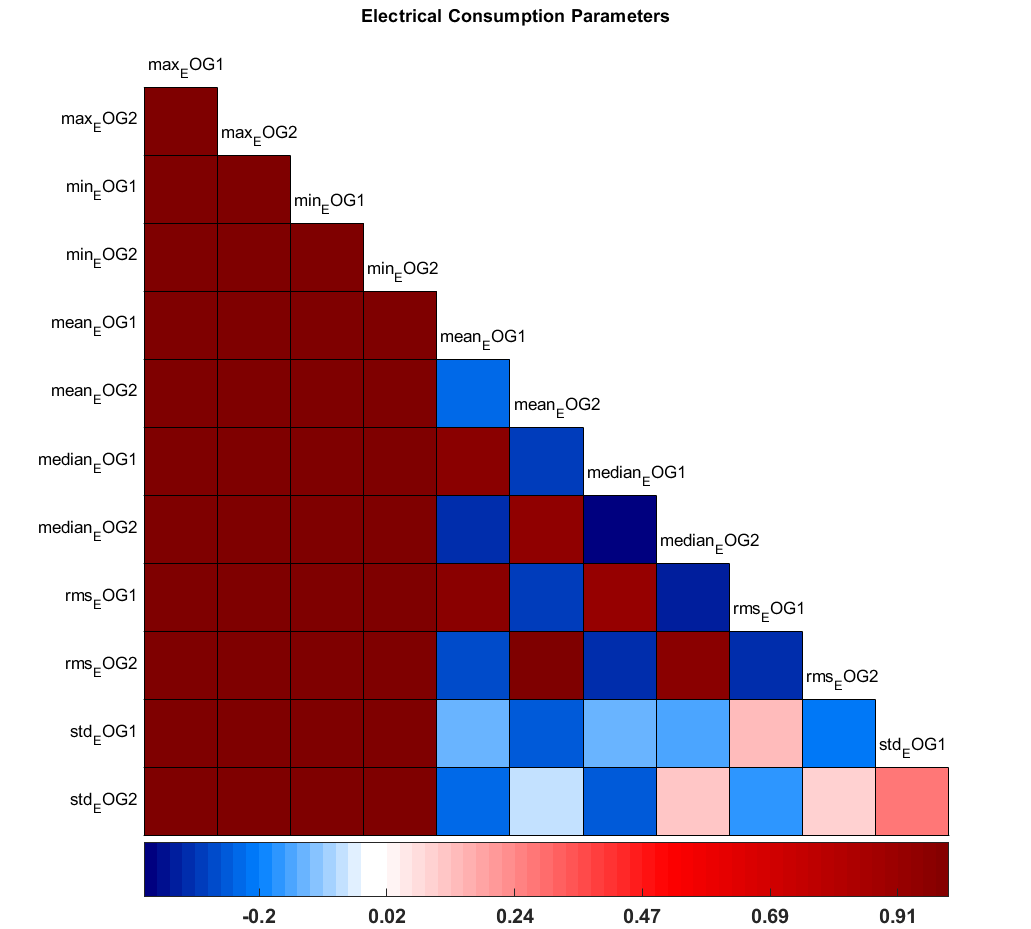

% Labels:
SongSystem_labels = {'max_EOG1','max_EOG2','min_EOG1','min_EOG2','mean_EOG1','mean_EOG2','median_EOG1','median_EOG2',...
        'rms_EOG1','rms_EOG2','std_EOG1','std_EOG2'};
% Load 20x20 Fisher Z correlation matrix, stored as variable 'corrmat' 
nROI = 20; % 20 regions of interest (ROIs)
sort_ind = [1:2:nROI,2:2:nROI]; % make all homotopic ROIs on 1 diagonal
[~, h_corrmat, h_colorbar] = plot_corrmat([],... % leave timeSeries input empty, since already calculated corrmat
    'corrmat', R,... % the correlation matrix
    'title', 'Electrical Consumption Parameters',... % plot title
    'labels', SongSystem_labels,... % correlation matrix cell labels
    'sort_ind', sort_ind,... % sort ROIs for plotting
    'label_FontSize', 10,... % long labels get cutoff with larger fonts
    'outline', 1); % outline the cells (appearance improvement)


%Remove NaN results
%mean(EOG1,EOG2), median(EOG1,EOG2), rms(EOG1,EOG2), std(EOG1,EOG2)
DataFeatureSelection=allData(5:end-1,5:end-1);%not including the label
R = corrcoef(DataFeatureSelection)

R =     1.0000   -0.2672    0.9536   -0.3481    0.9591   -0.3017   -0.1405   -0.2543
   -0.2672    1.0000   -0.3114    0.9407   -0.3272    0.9892   -0.2539   -0.0500
    0.9536   -0.3114    1.0000   -0.4089    0.9062   -0.3468   -0.1358   -0.2704
   -0.3481    0.9407   -0.4089    1.0000   -0.3755    0.9540   -0.1586    0.1213
    0.9591   -0.3272    0.9062   -0.3755    1.0000   -0.3487    0.1387   -0.1745
   -0.3017    0.9892   -0.3468    0.9540   -0.3487    1.0000   -0.2106    0.0913
   -0.1405   -0.2539   -0.1358   -0.1586    0.1387   -0.2106    1.0000    0.2631
   -0.2543   -0.0500   -0.2704    0.1213   -0.1745    0.0913    0.2631    1.0000


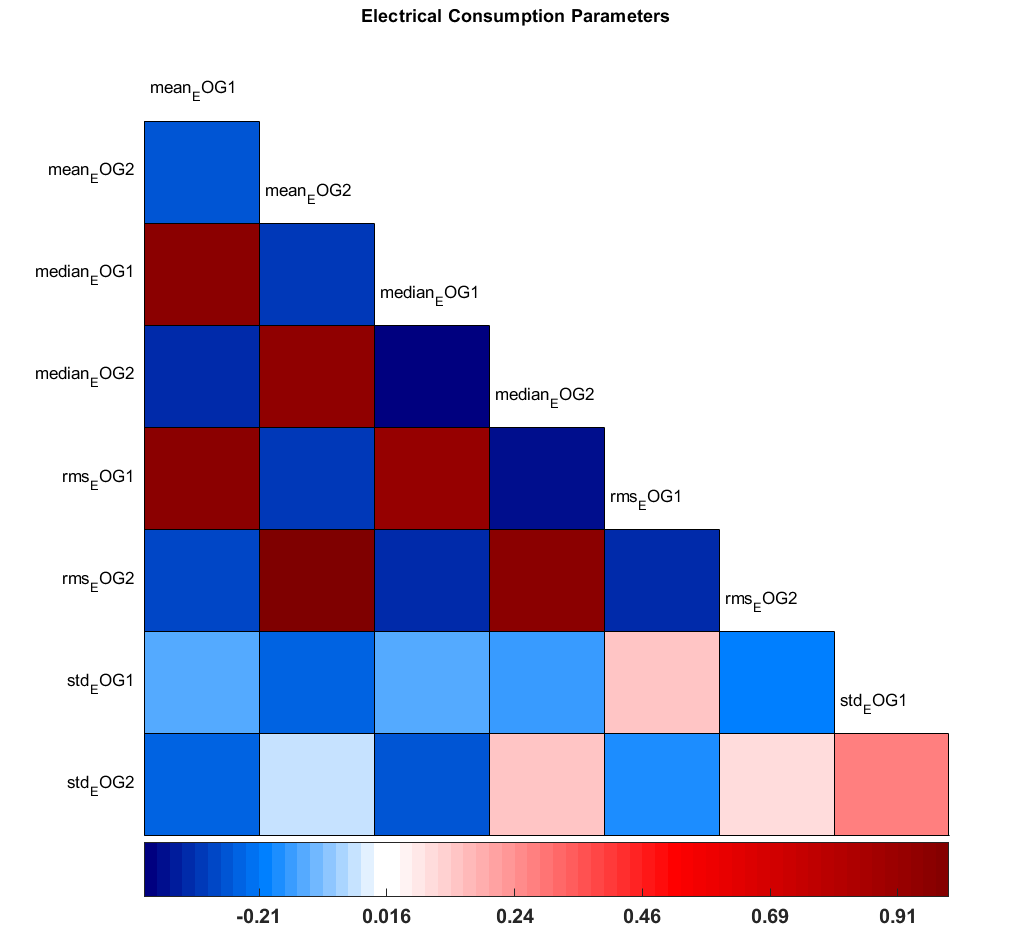

% Labels:
SongSystem_labels = {'mean_EOG1','mean_EOG2','median_EOG1','median_EOG2',...
        'rms_EOG1','rms_EOG2','std_EOG1','std_EOG2'};
% Load 20x20 Fisher Z correlation matrix, stored as variable 'corrmat' 
nROI = 20; % 20 regions of interest (ROIs)
sort_ind = [1:2:nROI,2:2:nROI]; % make all homotopic ROIs on 1 diagonal
[~, h_corrmat, h_colorbar] = plot_corrmat([],... % leave timeSeries input empty, since already calculated corrmat
    'corrmat', R,... % the correlation matrix
    'title', 'Electrical Consumption Parameters',... % plot title
    'labels', SongSystem_labels,... % correlation matrix cell labels
    'sort_ind', sort_ind,... % sort ROIs for plotting
    'label_FontSize', 10,... % long labels get cutoff with larger fonts
    'outline', 1); % outline the cells (appearance improvement)

%Remove High correlation beatwen mean, meadian and rms
%rms(EOG1,EOG2), std(EOG1,EOG2)
DataFeatureSelection=allData(9:end-1,9:end-1);%not including the label
R = corrcoef(DataFeatureSelection)

R =     1.0000   -0.3488    0.1381   -0.1756
   -0.3488    1.0000   -0.2031    0.0967
    0.1381   -0.2031    1.0000    0.2584
   -0.1756    0.0967    0.2584    1.0000


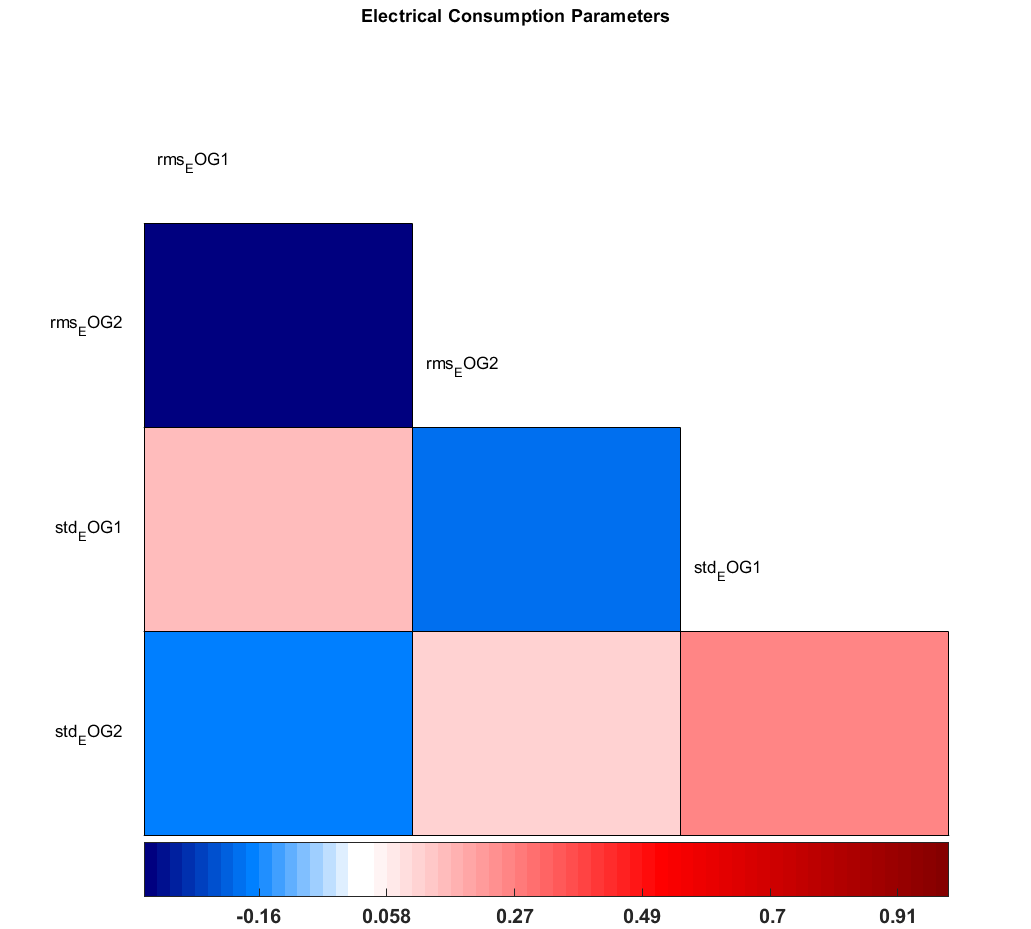

% Labels:
SongSystem_labels = {'rms_EOG1','rms_EOG2','std_EOG1','std_EOG2'};
% Load 20x20 Fisher Z correlation matrix, stored as variable 'corrmat' 
nROI = 20; % 20 regions of interest (ROIs)
sort_ind = [1:2:nROI,2:2:nROI]; % make all homotopic ROIs on 1 diagonal
[~, h_corrmat, h_colorbar] = plot_corrmat([],... % leave timeSeries input empty, since already calculated corrmat
    'corrmat', R,... % the correlation matrix
    'title', 'Electrical Consumption Parameters',... % plot title
    'labels', SongSystem_labels,... % correlation matrix cell labels
    'sort_ind', sort_ind,... % sort ROIs for plotting
    'label_FontSize', 10,... % long labels get cutoff with larger fonts
    'outline', 1); % outline the cells (appearance improvement)

%Save .CSV file with all EOG file features
csvwrite(strcat(datapath,'AllDataFeatures.csv'),allData(:,9:end));%Including the label

# Motor Task Classification (Label + 8)

All Classifications Results:

- 1) CN, MR, ML, MU, MD, MP = "0", "1", "2", "3", "4", "5"

- 2) CN, MR, ML = "0", "1", "2"

- 3) CN, MP = "0", "5"

- 4) CN, MU, MD = "0", "3", "4"

clear;clc;
addpath(genpath('./src'))%functions folders
path = fullfile('./data/');%data folder
% Upload .CSV file with the features of all EOG files
allData = fLoad_csv(path,'AllDataFeatures');

[CN, MR, ML, MU, MD, MP] = fIdxLabel_EOG(allData);%Index of rows by task type

num = input('Enter a number: ');
switch num
    case 1 %all task
        idx = [CN(1:end);MR(1:end);ML(1:end);MU(1:end);MD(1:end);MP(1:end)];
        disp('All task')
    case 2 %Horizontal Movements
        idx = [CN(1:end);MR(1:end);ML(1:end)];
        disp('Horizontal Movements')
    case 3 %Blinking
        idx = [CN(1:end);MP(1:end)];
        disp('Blinking')
    case 4 %Vertical Movement
        idx = [CN(1:end);MU(1:end);MD(1:end)];
        disp('Vertical Movement')
    otherwise
        disp('other value')
end

All task



TaskData=allData(idx,:);

# Open the Classification Learner

%regressionLearner
classificationLearner

1) CN, MR, ML, MU, MD, MP = "0", "1", "2", "3", "4", "5"

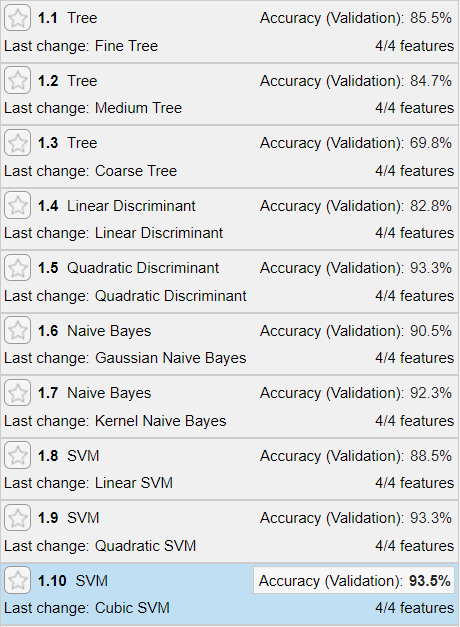

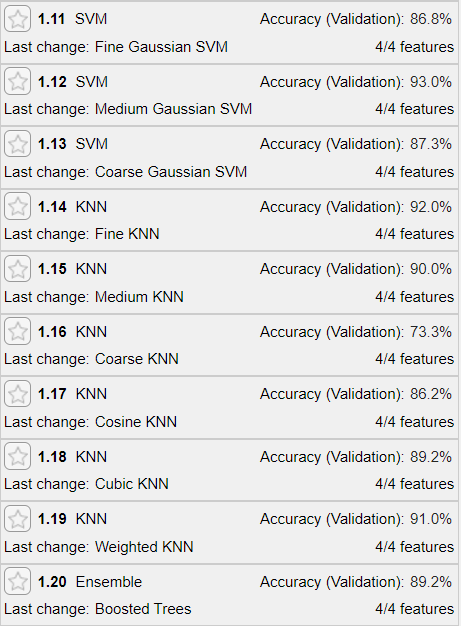

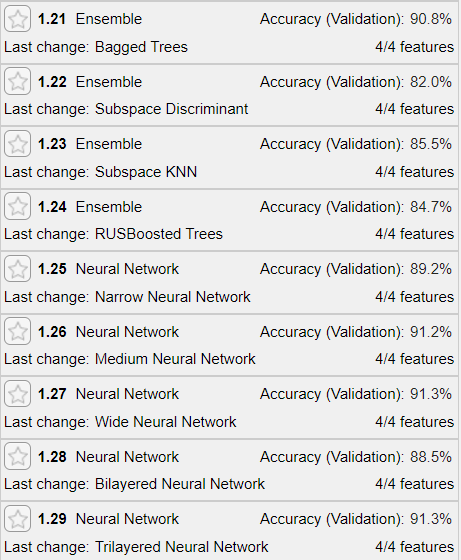

# Best Classification algorithm